Exercise 

Exercise 2.1:

In this exercise a set of data is created which is probability density is 2-d normal distribution. The mean value and covariance matrix for the sample generator are preset. Later on the real mean value and covariance matrix are compared to the true ones. One can see that as the number of samples is increased, these values will get closer to the true values.

We plot a true probability density function to visualize what the distribution should look like. Additioanlly we plot a 2d histogram of values based on the sampled data. Initailly it is expected that we will get a smooth histogram plot as in the 1d example from exercise 1. We notice that with the same number of samples the histogram is still very sparse. This is due to the dimensionality curse. As the dimensionality grows the required number of samples also grows exponentially. As before there was for example only 100 fields to fill, after increasing the dimensionality there is 100*100 which will mean that it is required to have way more samples to fill it nicely.

**Ask about the solution to this problem: smaller bins or more samples?**

Increasing samples should be "solution" to this problem, increasing number of bins will make it rather worse, it looks better on plot only

Exercise 2.2:

We used the script to visualize the meaning of variance and covariance. Having 2-d normal distribution, each of the variables has it's variance which describies how much x1 and x2 is spread around it's mean values. Additionally there are covariance elements which explain how dependent the variables are on eachother. There may be a trend that whenever x1 is larger than µ1, x2 is also larger than µ2, and that whenever x1 is smaller than µ1, x2 is also smaller than µ2. In such a case, x1 and x2 are not independent, and they are said to be correlated. 

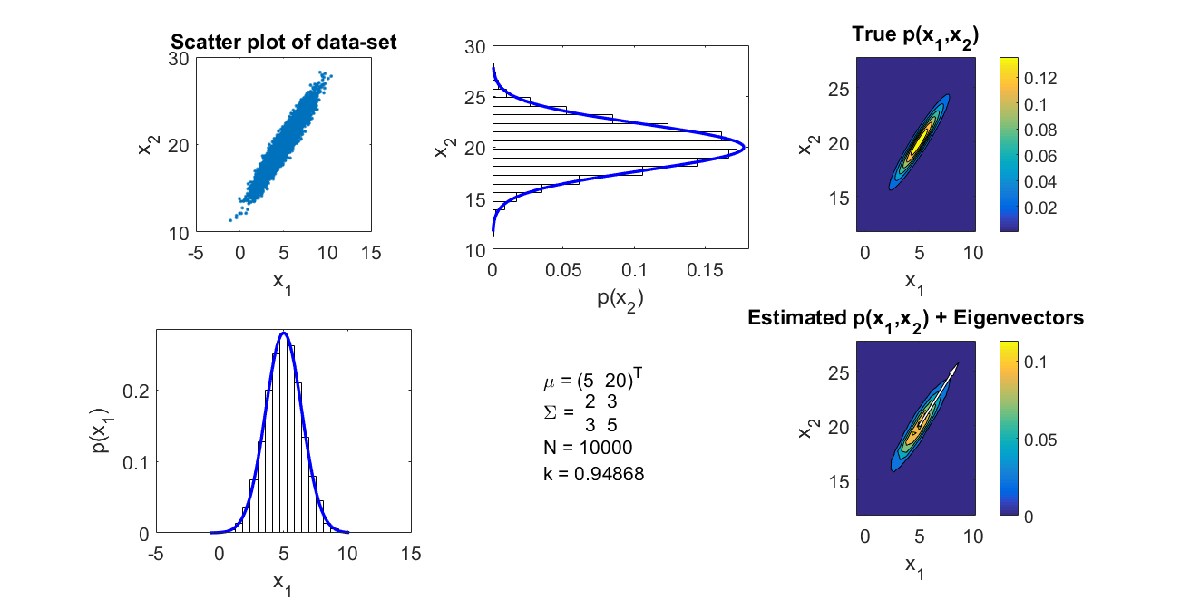

  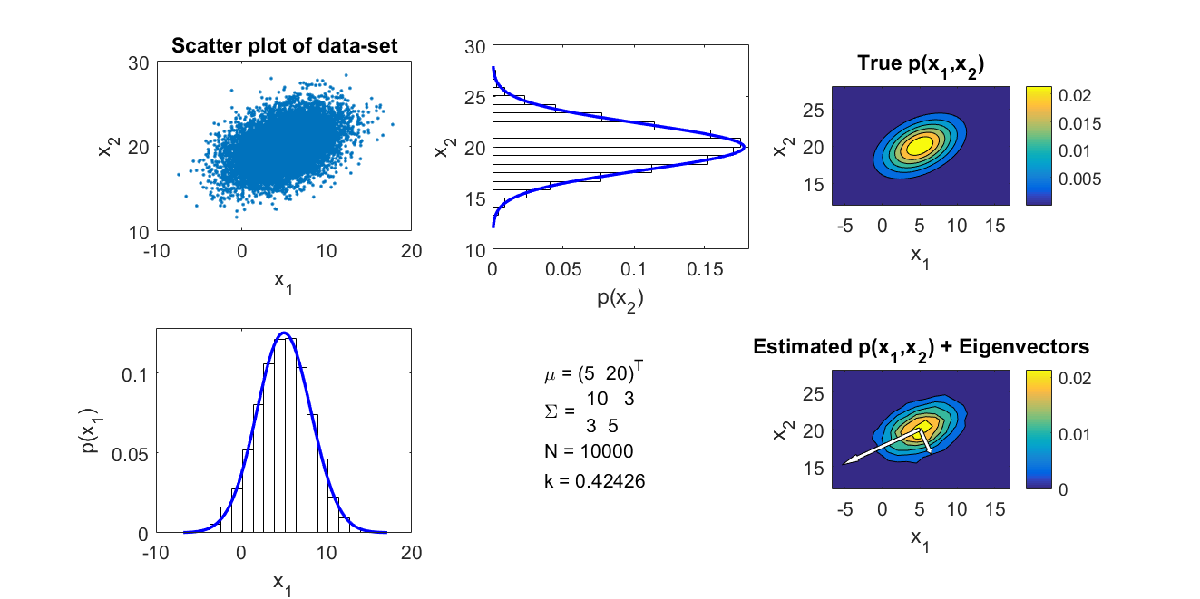

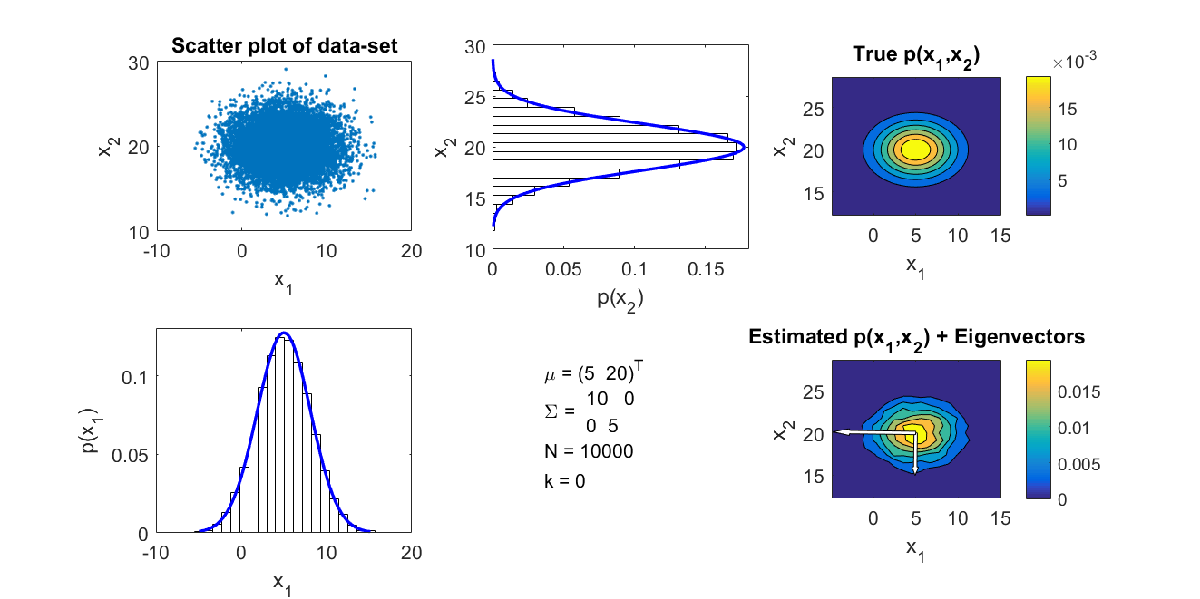

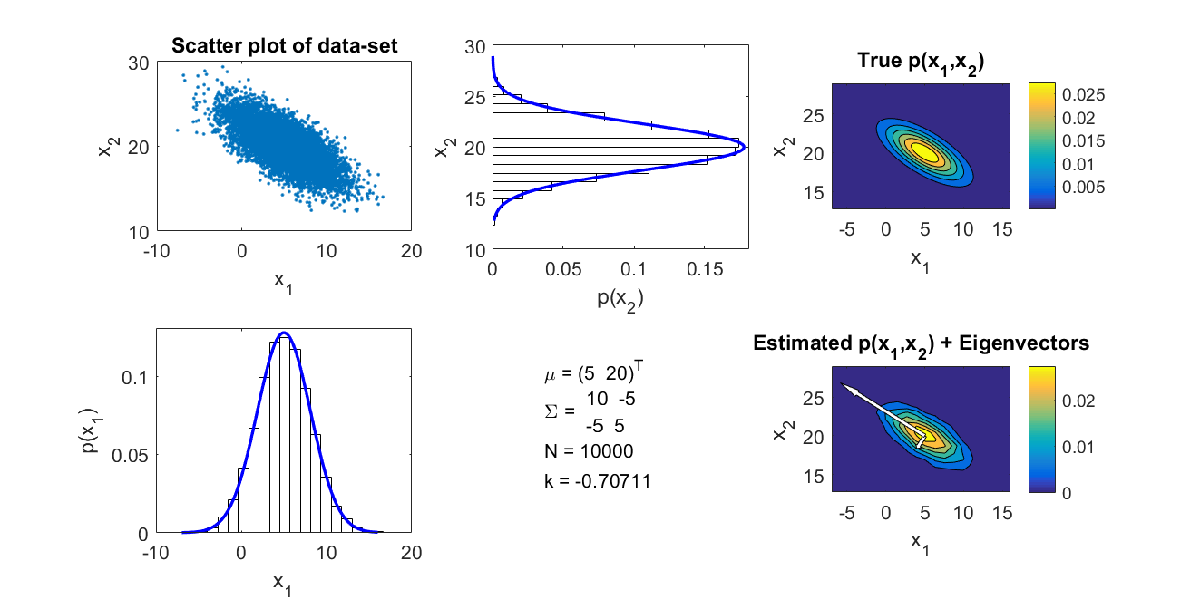

In the exercise the correlation coefficient is also calculated. It allows to describe how strong the correlation between components is (normalized covariance). As it's normalized it has values between -1 and 1. The border cases correspond to linear dependency between variables, in which case there is actually only one random variable.

 **Ask question about [-1; 1] -> **It cannot be exactly 1 or -1 as then the matrix is not positive definite.

Additionally the eigenvectors and eigenvalues of the covariance matrix are calculated. The eigenvector of the largest eigenvalue tells us the direction in which the singal variance is the largest.  It can be used when we want to reduce the dimensionality of the system. In that case we want to caast samples on the axis of largest variance to keep as much information as possible. For example if we cast on axis perpendicular, a lot of samples will be casted to the same point as the variance is very small. 

If the covariance is zero then eigenvalues give variances of the variables.If the covariance matrix of our data is a diagonal matrix, such that the covariances are zero, then this means that the variances must be equal to the eigenvalues. The largest eigenvector of the covariance matrix always points into the direction of the largest variance of the data, and the magnitude of this vector equals the corresponding eigenvalue. The second largest eigenvector is always orthogonal to the largest eigenvector, and points into the direction of the second largest spread of the data.

**Comment on the dependence of the orientation and shape of the ellipsoids in the contour plots of quadratic form induced by the covariance matrix: **

This was alreaddy done by us showing few cases:

-coefficient is ~1 or ~-1 -> the result is a straight line

-no covariance - evenly spread circle/elipsoid data with eigenvectors along x and y axis

-positive covariance tilting one way

-negative covariance - tilting the other way

**Exercise 3**

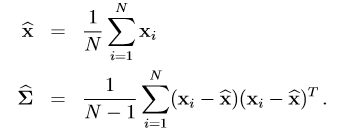

In sigma, the multiplication is vertical vector by horizontal vector - that's why you get 2x2 matrix.

The first multiplication rotates the coordinate system. It also removed the covariance elements. In that case the left variances will be equal to the eigenvalues. It was explained by Lars on the papers that we have.

In Lars notes we start with calculating E(...) which will give us covariance matrix of the result. We get to U'SigmaU, which using eigenvector laws will give us U'U*lambda. Then because the original matrix (covariance) is symetrical we know that U'U = I.

The other operation is just a simple scaling to go to unit variances.

The geometrical signficance I have already explained in exercise 2.2. I did not compare the transformed data-sets from different distributions, it should be done but the expected behaviour is that it casts all of them tot he same distribution.

The first term is used to rotate, the other term is used to scale to variance of value 1. Removing it will leave us with signal of 0 mean but with not unit covariance.

**Exercise 4**

You can see that once you transform signals (keeping the original variance/covariance), you can decide which directions carry the most of the signal variance and remove the ones with very little variance.

In the first example example the two signals are very close to eachother so it's hard to do a split. It can be seen by looking at the magnitude of eigenvvalues that they are kind of close to eachother. It is not a very good example to reduce the dimensionality.

In the other example the signals are strongly split and it can be seen by looking at the magnitude of eigenvalues, one greatly larger than the other. In that case we can reduce dimensionality by removing the small magnitude variable. 